## Reaction Kinetics Data

Let's assume that A and B react to form C and as this reaction happens, color changes. By keeping the concentration of A constant and varying the concentration of B and temperature, we measure how long it takes to observe the color change. This type of reaction kinetics could be used in the stopping mechanism of a Chem-E-Car.

Chemical reaction:


$$A+B\to C$$


We captured our reaction kinetics data in Excel spreadsheets.

## Load Reaction Kinetics Data

After importing data using "Import Data" button on MATLAB toolstrip for the selected spreadsheet, automatically generate a function using "Import Selection" drop down and call this function to import the rest of the data using a for loop.

rxn_data = readtable("rxn_data1GAB.xlsx")

rxn_data = 36×4 table
    A_M      B_M     Temperature_K    Time_s
    ____    _____    _____________    ______
    0.02     0.03         290          13.9 
    0.02    0.025         290          16.1 
    0.02     0.02         290          20.2 
    0.02    0.015         290          28.7 
    0.02     0.01         290          48.3 
    0.02    0.005         290         165.7 
    0.02     0.03         292          12.8 
    0.02    0.025         292          13.7 
    0.02     0.02         292          18.3 
    0.02    0.015         292            25 
    0.02     0.01         292            43 
    0.02    0.005         292         146.8 
    0.02     0.03         296          11.7 
    0.02    0.025         296          13.2 
    0.02     0.02         296          15.8 
    0.02    0.015         296          23.5 

## Visualize Reaction Kinetics Data

After importing the data, we can click on one of the tables were we have the data and using "Plots" tab in the Home tab of MATLAB, we can visualize time vs. concentration data as a scatter plot for a given temperature.

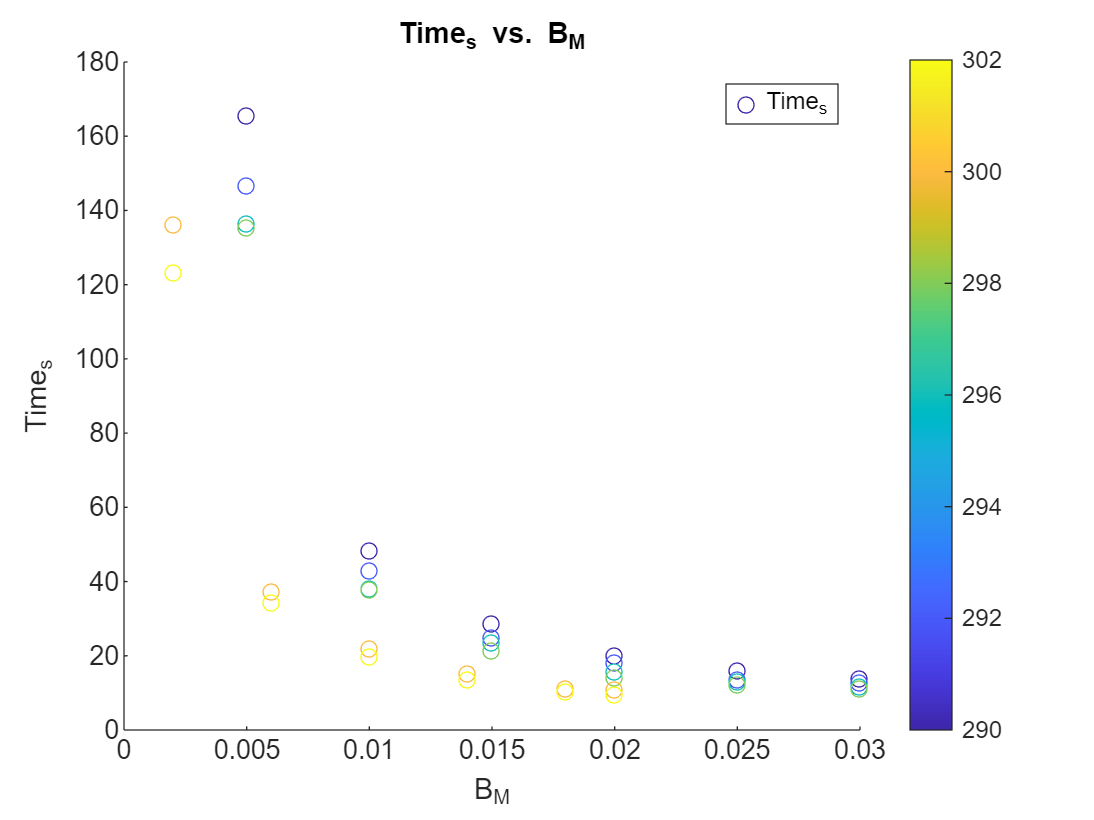

% Create scatter of selected data
s = scatter(rxn_data,"B_M","Time_s","ColorVariable","Temperature_K","DisplayName","Time_s");

% Add xlabel, ylabel, title, and legend
xlabel("B_M")
ylabel("Time_s")
title("Time_s vs. B_M")
legend

colorbar

list_temperatures = unique(rxn_data.Temperature_K);
idx = rxn_data.Temperature_K == list_temperatures(1);
data_selected = rxn_data(idx,:);
fprintf('The variable data_selected shows data for %d K',data_selected.Temperature_K(1) )

The variable data_selected shows data for 290 K

## Fit Curves to Reaction Kinetics Data

Using "Curve Fitter" App in the Apps tab of MATLAB (this app is a part of Curve Fitting Toolbox, if you don't have it in the "Apps" tab, you can add it using "Add-Ons"), fit equations to the data. You can also explore various relationships interactively using this tool. Here, we fitted an exponential relationship by assigning Chemical B's concentration data to x variable and time data to y variable.

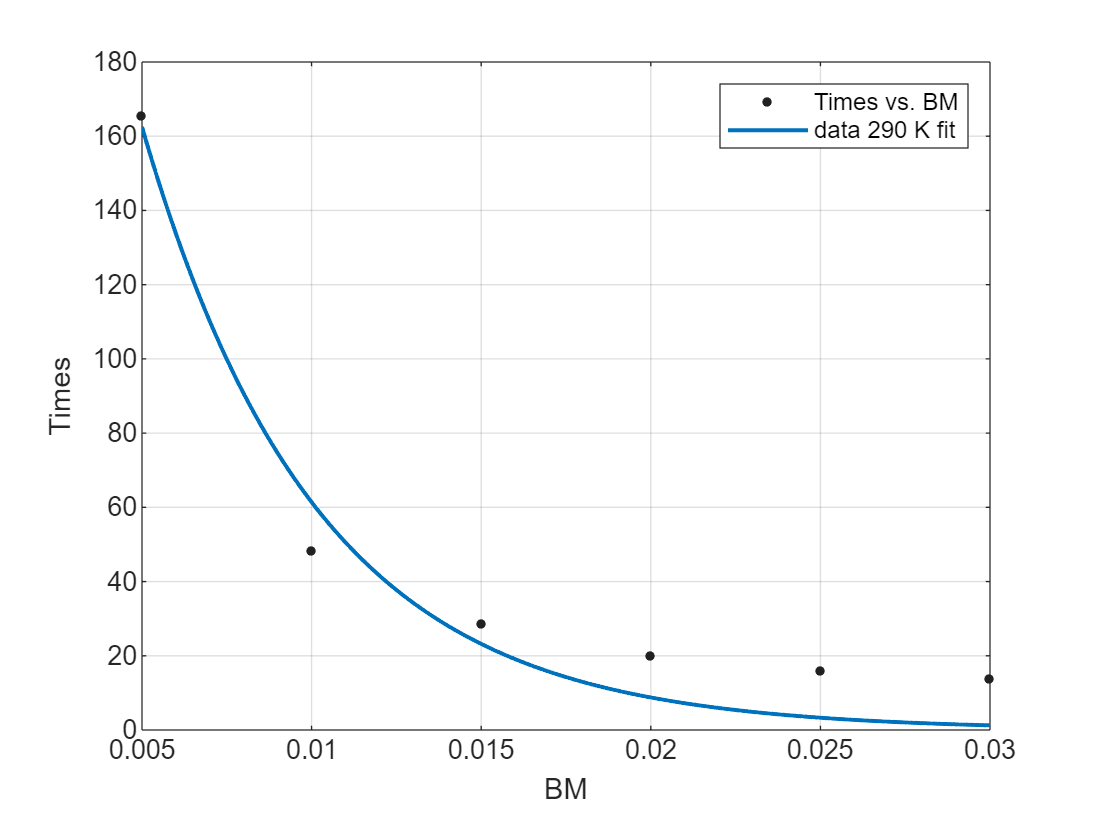

fitresult =      General model Exp1:
     fitresult(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       430.1  (181.5, 678.6)
       b =      -194.6  (-287.4, -101.9)

gof = struct with fields:
           sse: 666.3536
       rsquare: 0.9612
           dfe: 4
    adjrsquare: 0.9515
          rmse: 12.9069

[fitresult, gof] = createFit(data_selected.B_M, data_selected.Time_s)

You can fit curves to the data collected at the other temperatures as well.

You can also explore the relationship between time, concentration and temperature. To investigate that, let's merge our dataset intro one table.

%kineticdata=[rxnData.T290; rxnData.T292; rxnData.T296; rxnData.T298; rxnData.T300; rxnData.T302];

Using  "Curve Fitter" App, let's fit a surface:

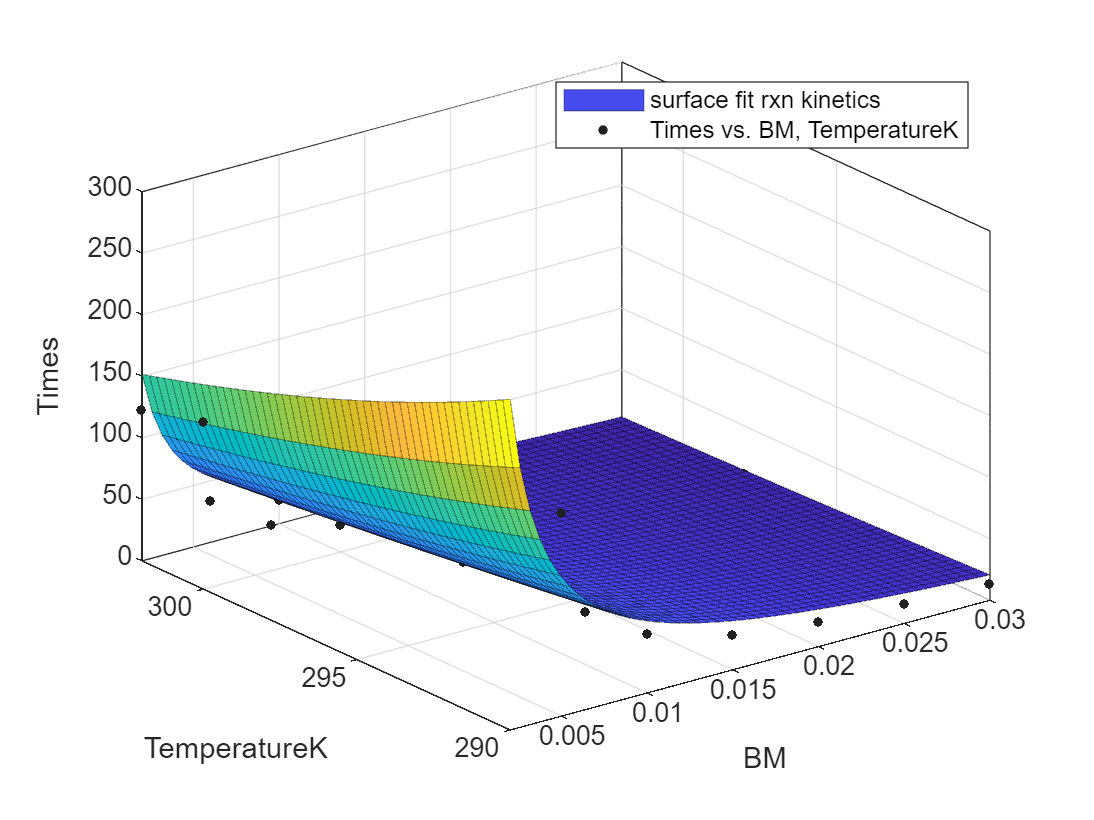

surffitresult =      General model:
     surffitresult(x,y) = a*exp(-b/y)*(x^c)
     Coefficients (with 95% confidence bounds):
       a =   4.085e-07  (-4.092e-06, 4.909e-06)
       b =       -4180  (-7246, -1115)
       c =     -0.9478  (-1.156, -0.7398)

surfgof = struct with fields:
           sse: 1.5534e+04
       rsquare: 0.7964
           dfe: 33
    adjrsquare: 0.7841
          rmse: 21.6961

[surffitresult, surfgof] = createSurfaceFit(rxn_data.B_M, rxn_data.Temperature_K, rxn_data.Time_s)

## How to systematically collect data?

- [Design of Experiments ](https://www.mathworks.com/help/stats/design-of-experiments-1.html)

## Further Resources

- [Chem-E-Car Competition resources](https://www.mathworks.com/academia/student-competitions/aiche-chem-e-car.html)

- [MATLAB Academy](https://matlabacademy.mathworks.com/?page=1&sort=featured)

## References

[1] [CHEM-E-CAR: IODINE CLOCK REACTION, Guillermo Díaz Sainz, 2015](https://repositorio.unican.es/xmlui/bitstream/handle/10902/6696/376369.pdf?sequence=1)